## Problem Distance Protection 3: Phase to ground

Consider the simple 13.8 kV system represented by the one-line diagram below. 

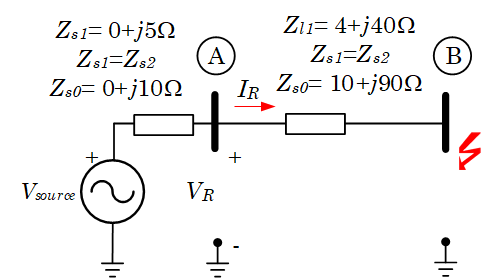

Verify the distance calculation for a 

(a) three-phase, 

(b) phase-to-phase, and

**(c) phase-to-ground faults.**

Created by: Professor Francisco Gonzalez-Longatt, March 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

#GitHub: [https://github.com/fglongatt/PowerSystemProtections](https://github.com/fglongatt/PowerSystemProtections) 

#ResearchGate: [https://www.researchgate.net/project/Power-System-Protection-13](https://www.researchgate.net/project/Power-System-Protection-13) 

clc
clear all

System Data

Vll = 13.8e3;        % Vll: Nominal line-to-line voltage in Volts
Vln = Vll / sqrt(3); % Vlb: Nomianl line to neutral voltage in Volts
VT = Vln;

The sequence impedance of the source (Zs2 = Zs1);

Zs1 = 0 + 5*i;
Zs0 = 0 + 10*i;

The sequence impedance of the line (Zl2 = Zl1);

Zl1 = 4 + 40*i;
Zl0 = 10 + 90*i;

#### Phase to Ground fault

For this fault, the three symmetrical components of the current are equal

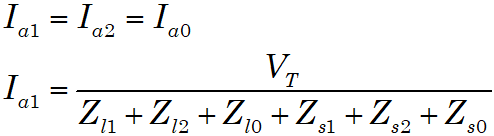

Zs2 = Zs1;
Zl2 = Zl1;
Ia1 = VT/ ( Zs1 + Zl1 + Zs2 + Zl2 + Zs0 + Zl0);
Ia2 = Ia1;
Ia0 = Ia1;
fprintf(' Ia1 = (%5.5f ∠ %5.5f°) A', abs(Ia1), angle(Ia1)*180/pi)

 Ia1 = (41.74694 ∠ -84.58813°) A

fprintf(' Ia1 = (%5.5f + j%5.5f) A', real(Ia1),imag(Ia1))

 Ia1 = (3.93734 + j-41.56085) A


fprintf(' Ia2 = (%5.5f ∠ %5.5f°) A', abs(Ia2), angle(Ia2)*180/pi)

 Ia2 = (41.74694 ∠ -84.58813°) A

fprintf(' Ia2 = (%5.5f + j%5.5f) A', real(Ia2),imag(Ia2))

 Ia2 = (3.93734 + j-41.56085) A


fprintf(' Ia0 = (%5.5f ∠ %5.5f°) A', abs(Ia2), angle(Ia2)*180/pi)

 Ia0 = (41.74694 ∠ -84.58813°) A

fprintf(' Ia0 = (%5.5f + j%5.5f) A', real(Ia2),imag(Ia2))

 Ia0 = (3.93734 + j-41.56085) A

And the phase a voltage  at the relay location:

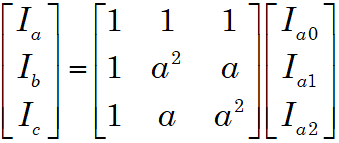

I012 = [Ia0; Ia1; Ia2];
a = 1*exp (i*120*pi/180);
A= [1 1 1; 1 a^2 a; 1 a a^2];
Iabc = A * I012;

Separating the components

Ia = Iabc(1);
Ib = Iabc(2);
Ic = Iabc(3);
% Printing results
fprintf(' Ia = (%5.5f ∠ %5.5f°) A', abs(Ia), angle(Ia)*180/pi)

 Ia = (125.24082 ∠ -84.58813°) A

fprintf(' Ia = (%5.5f + j%5.5f) A', real(Ia),imag(Ia))

 Ia = (11.81203 + j-124.68255) A


fprintf(' Ib = (%5.5f ∠ %5.5f°) A', abs(Ib), angle(Ib)*180/pi)

 Ib = (0.00000 ∠ 26.56505°) A

fprintf(' Ib = (%5.5f + j%5.5f) A', real(Ib),imag(Ib))

 Ib = (0.00000 + j0.00000) A


fprintf(' Ic = (%5.5f ∠ %5.5f°) A', abs(Ic), angle(Ic)*180/pi)

 Ic = (0.00000 ∠ 26.56505°) A

fprintf(' Ic = (%5.5f + j%5.5f) A', real(Ic),imag(Ic))

 Ic = (0.00000 + j0.00000) A

The symmetric components of the voltages at the relay location are

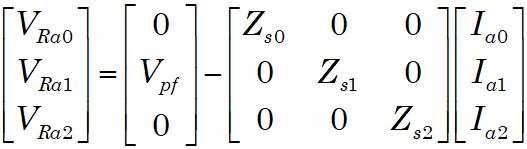

VRa1 = VT - Zs1 * Ia1;
VRa2 = 0 - Zs2 * Ia2;
VRa0 = - Zs0 * Ia0;
% Printing results
fprintf(' VRa1 = (%5.5f ∠ %5.5f°) V', abs(VRa1), angle(VRa1)*180/pi)

 VRa1 = (7759.65444 ∠ -0.14536°) V

fprintf(' VRa1 = (%5.5f + j%5.5f) V', real(VRa1),imag(VRa1))

 VRa1 = (7759.62946 + j-19.68672) V


fprintf(' VRa2 = (%5.5f ∠ %5.5f°) V', abs(VRa2), angle(VRa2)*180/pi)

 VRa2 = (208.73470 ∠ -174.58813°) V

fprintf(' VRa2 = (%5.5f + j%5.5f) V', real(VRa2),imag(VRa2))

 VRa2 = (-207.80425 + j-19.68672) V


fprintf(' VRa0 = (%5.5f ∠ %5.5f°) V', abs(VRa0), angle(VRa0)*180/pi)

 VRa0 = (417.46939 ∠ -174.58813°) V

fprintf(' VRa0 = (%5.5f + j%5.5f) V', real(VRa0),imag(VRa0))

 VRa0 = (-415.60850 + j-39.37344) V

And the phase a voltage  at the relay location:

% Symmetrical component
VR012 = [VRa0; VRa1; VRa2];
a = 1*exp (i*120*pi/180);
A= [1 1 1; 1 a^2 a; 1 a a^2];
VRabc = A * VR012;
% Separating the components
VRa = VRabc(1);
VRb = VRabc(2);
VRc = VRabc(3);
% Printing results
fprintf(' VRa = (%5.5f ∠ %5.5f°) V', abs(VRa), angle(VRa)*180/pi)

 VRa = (7136.65118 ∠ -0.63222°) V

fprintf(' VRa = (%5.5f + j%5.5f) V', real(VRa),imag(VRa))

 VRa = (7136.21671 + j-78.74687) V


fprintf(' VRb = (%5.5f ∠ %5.5f°) V', abs(VRb), angle(VRb)*180/pi)

 VRb = (8090.17388 ∠ -121.20491°) V

fprintf(' VRb = (%5.5f + j%5.5f) V', real(VRb),imag(VRb))

 VRb = (-4191.52111 + j-6919.68672) V


fprintf(' VRc = (%5.5f ∠ %5.5f°) V', abs(VRc), angle(VRc)*180/pi)

 VRc = (8056.52283 ∠ 121.34998°) V

fprintf(' VRc = (%5.5f + j%5.5f) V', real(VRc),imag(VRc))

 VRc = (-4191.52111 + j6880.31328) V

The zero-sequence current compensation factor K is given by

K = (Zl0 -Zl1)/Zl1;

K = 1.2525 - 0.0248i

fprintf('Zero-sequence current compensation factor K \n')

Zero-sequence current compensation factor K 


fprintf(' K = (%5.5f ∠ %5.5f°) ', abs(K), angle(K)*180/pi)

 K = (1.25272 ∠ -1.13218°) 

fprintf(' K = (%5.5f + j%5.5f) ', real(K),imag(K))

 K = (1.25248 + j-0.02475) 

and the compensated phase a current is I'a = Ia + KI0

Ia = Ia + K * Ia0;
fprintf(' Ia = (%5.5f ∠ %5.5f°) A', abs(Ia), angle(Ia)*180/pi)

 Ia = (177.53083 ∠ -84.92163°) A

fprintf(' Ia = (%5.5f + j%5.5f) A', real(Ia),imag(Ia))

 Ia = (15.71472 + j-176.83395) A

Finally, 

The fault impedance (Zf) seen by the relay in this case is

Zf = VRa / Ia;
fprintf(' Zf = (%5.5f ∠ %5.5f°) Ω', abs(Zf), angle(Zf)*180/pi)

 Zf = (40.19950 ∠ 84.28941°) Ω

fprintf(' Zf = (%5.5f + j%5.5f) ΩHave a ', real(Zf),imag(Zf))

 Zf = (4.00000 + j40.00000) ΩHave a 